clear
dxDir = load('dxDir.mat').dxDir

$$dxDir = \left(\begin{array}{c} v\,\cos\left(\theta_{t}\right)\\ v\,\sin\left(\theta_{t}\right)\\ \frac{v\,\tan\left(\delta_{t}\right)}{L_{t}}\\ -\frac{v\,\tan\left(\delta_{t}\right)}{L_{t}}-\frac{v\,\sin\left(\delta_{i}+\varphi +\mathrm{atan}\left(\frac{L_{h}\,\tan\left(\delta_{t}\right)}{L_{t}}\right)\right)\,\sqrt{{L_{h}}^{2}\,{\tan\left(\delta_{t}\right)}^{2}+{L_{t}}^{2}}}{L_{i}\,L_{t}\,\sin\left(\delta_{i}-1.5708\right)} \end{array}\right)$$

dxAB = load('dxAB.mat').dX

$$dxAB = \left(\begin{array}{c} v\,\cos\left(\theta_{t}\right)\\ v\,\sin\left(\theta_{t}\right)\\ \frac{v\,\tan\left(\delta_{t}\right)}{L_{t}}\\ \frac{v\,\sin\left(\delta_{i}+\varphi +\mathrm{atan}\left(\frac{L_{h}\,\tan\left(\delta_{t}\right)}{L_{t}}\right)\right)\,\sqrt{\frac{{L_{h}}^{2}\,{\tan\left(\delta_{t}\right)}^{2}}{{L_{t}}^{2}}+1}}{L_{i}\,\cos\left(\delta_{i}\right)}-\frac{v\,\tan\left(\delta_{t}\right)}{L_{t}} \end{array}\right)$$

% dxRejoin = load('dxRejoin.mat').dxRejoin

isequal(dxDir, dxAB)

ans = logical
   0



L_t = 2;
L_h = 0.75;
L_i = 1;

x = 2;
y = 2;
% theta_t = pi-pi/12;
theta_t = -pi:0.05:pi;
phi = pi/12;

v = 1;
delta_t = 0;
% delta_t = -pi/4:0.01:pi/4;
delta_i = 0;

dxDirV = eval(subs(dxDir));
dxABV = eval(subs(dxAB));
% dxRejoinV = eval(subs(dxRejoin));

dxRejoin = zeros(4,length(theta_t));
for i = 1:length(theta_t)
    [A,B] = getAB([L_t,L_h,L_i]',[x;y;theta_t(i);phi],[v;delta_t;delta_i]);
    dX = A*[x;y;theta_t(i);phi] + B*[v;delta_t;delta_i];
    dxRejoin(:,i) = dX;
end

names = {'d x','d y','d theta_t', 'd phi'}

names = 1×4 cell array
    {'d x'}    {'d y'}    {'d theta_t'}    {'d phi'}


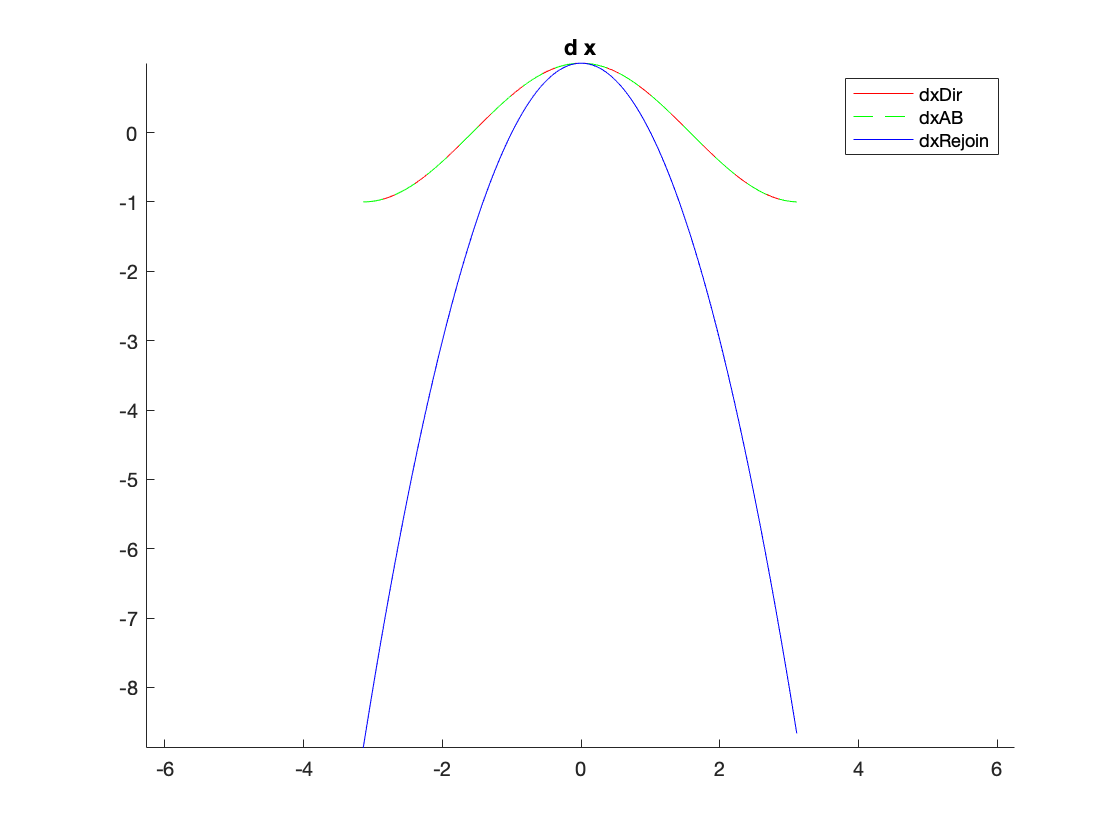

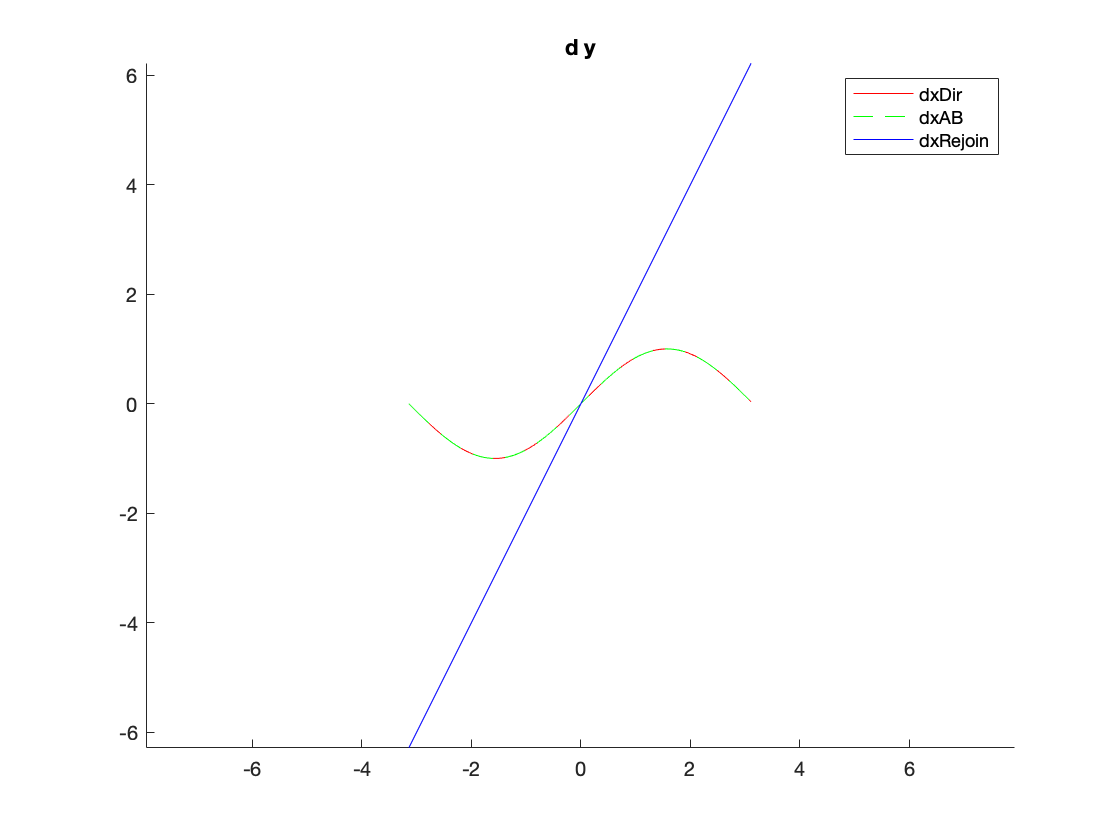

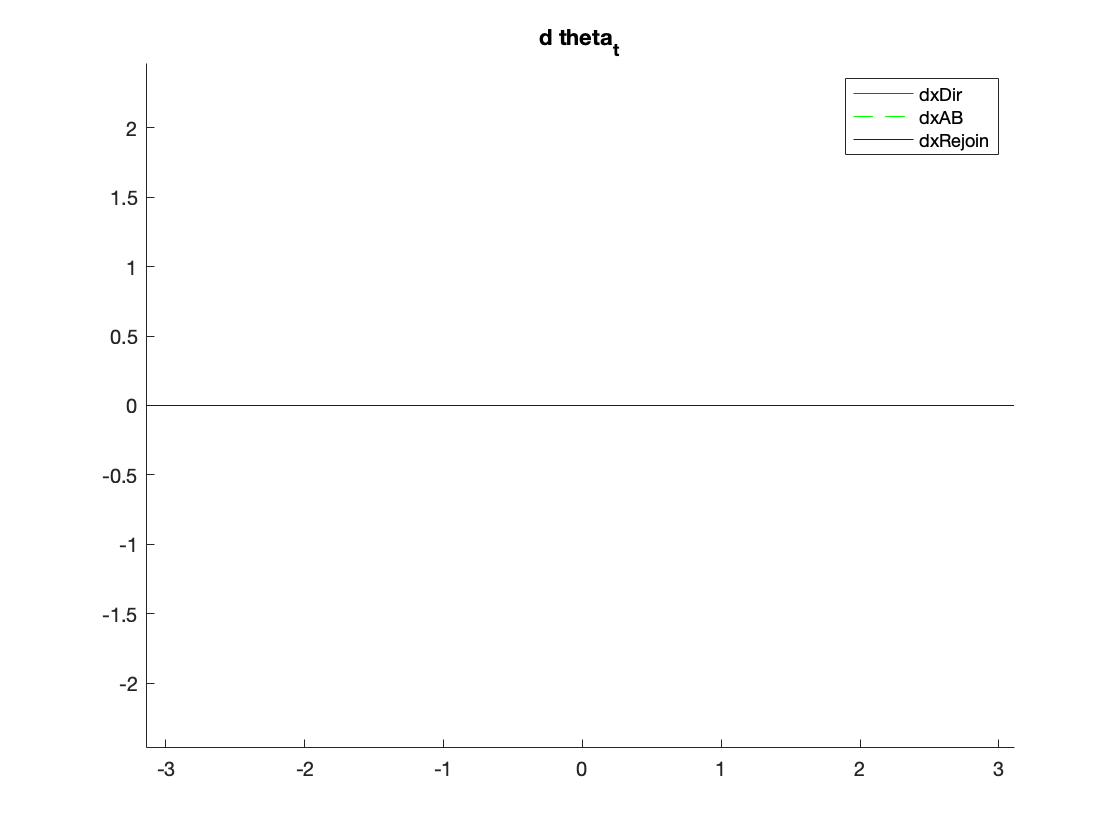

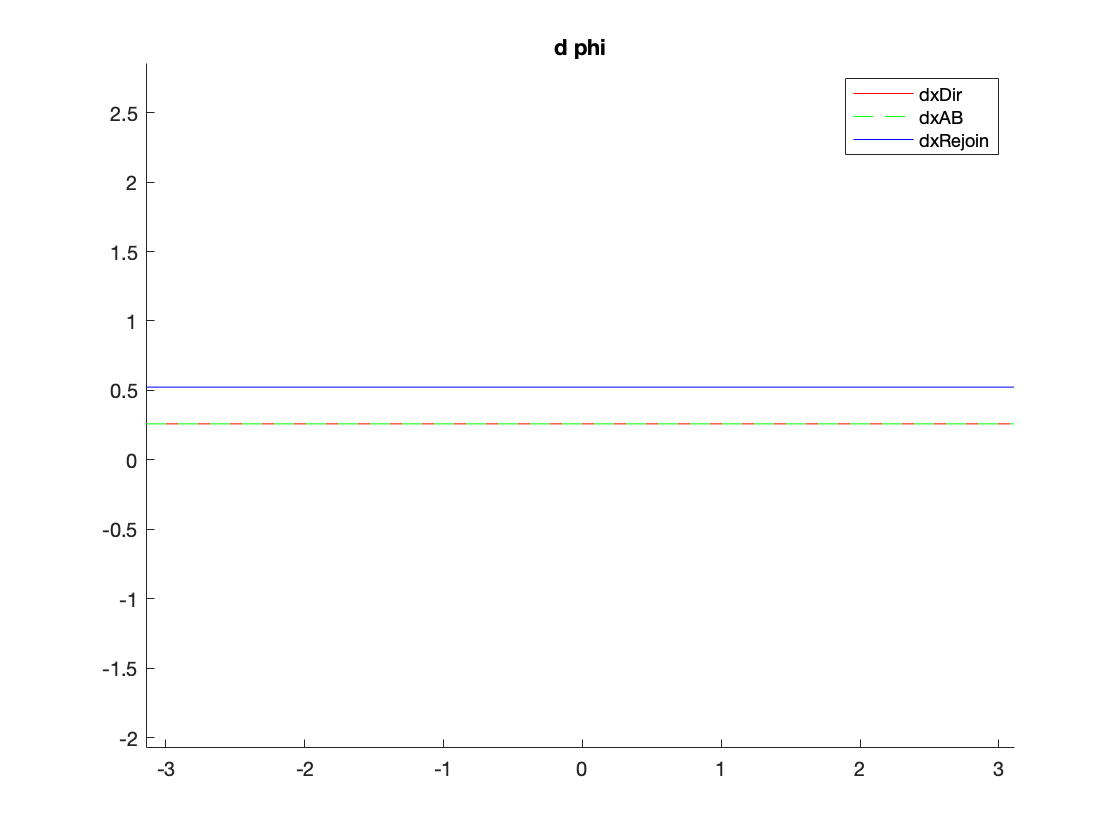

for i = 1:4
    figure(i), clf, hold on
    plot(theta_t,dxDirV(i,:),'r');
    plot(theta_t,dxABV(i,:),'--g');
    plot(theta_t,dxRejoin(i,:),'b');
    legend('dxDir','dxAB','dxRejoin')
    title(names{i})
    axis equal
end